clearvars

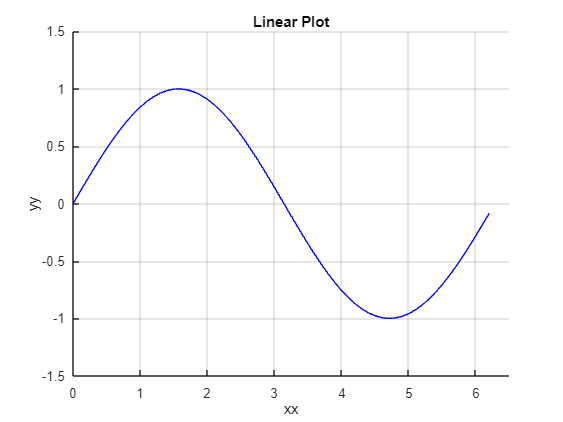

%% Example 1: Basic Linear Plot
x_lin = 0:0.1:2*pi;
y_lin = sin(x_lin);


graphics(y_lin, x_lin, ...         % y and x data
        [-1.5 1.5], [0 6.5], ...  % y-range, x-range
        'b', '-', 'linear', 'Linear Plot', 'xx', 'yy');       % blue solid line, linear plot

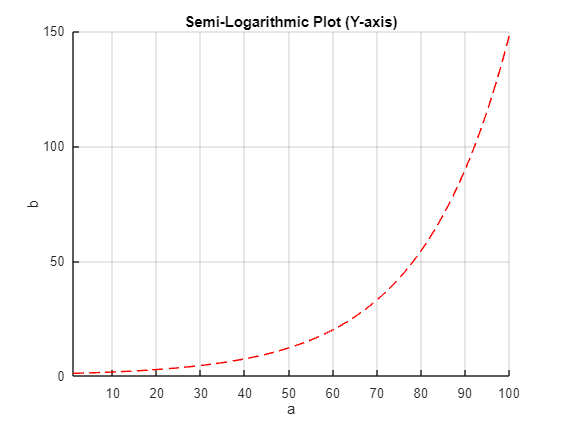


%% Example 2: Logarithmic Y-Axis Plot
x_log = linspace(1, 100, 100);
y_log = exp(x_log/20);

graphics(y_log, x_log, ...
        [], [1 100], ...          % auto y-range, fixed x-range
        'r', '--', 'logy', 'Semi-Logarithmic Plot (Y-axis)', 'a', 'b');       % red dashed line, log-Y plot

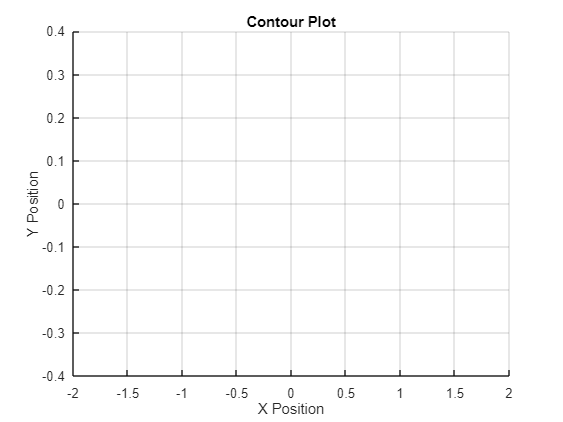


%% Example 3: Contour Plot
% Create grid data
x_cont = linspace(-2, 2, 50);
y_cont = linspace(-2, 2, 50);
[X,Y] = meshgrid(x_cont, y_cont);
Z = X.*exp(-X.^2 - Y.^2);  % Sample function

graphics(Z, x_cont, ...     % Z matrix as y input
        [-0.4 0.4], [], ... % y-range (for color levels), auto x-range
        'jet', '-', 'contour', 'Contour Plot', 'X Position', 'Y Position'); % 'jet' colormap for contour

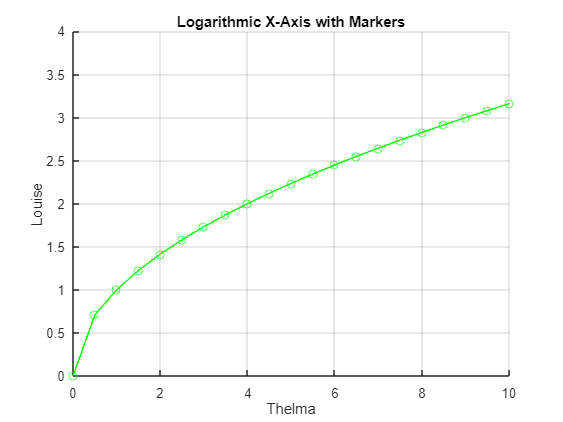


%% Example 4: Combined Line Specifiers
x_comb = 0:0.5:10;
y_comb = sqrt(x_comb);

graphics(y_comb, x_comb, ...
        [0 4], [0 10], ...
        'g', 'o-', 'logx', 'Logarithmic X-Axis with Markers', 'Thelma', 'Louise'); % green circle-marked line, log-X plot

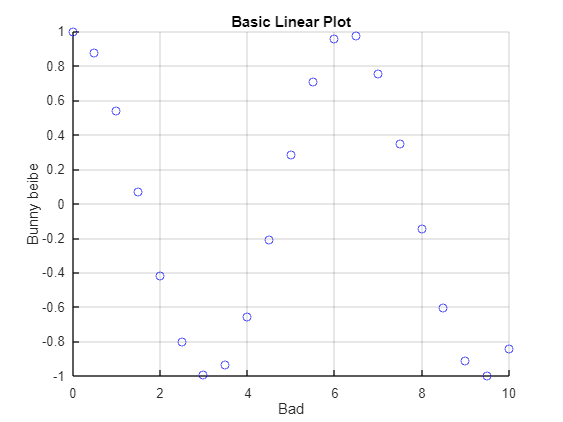

%% Example 4: Combined Line Specifiers
x_comb = 0:0.5:10;
y_comb = cos(x_comb);

graphics(y_comb, x_comb, ...
        [-1 1], [0 10], ...
        'b', 'o', 'linear', 'Basic Linear Plot', 'Bad', 'Bunny beibe'); % green circle-marked line, log-X plot